# ANOVA Example

Nick Stites

GEEN 3853

10/14/2020

## INTRODUCTION

For this ANOVA example, we are looking at two farming processes--4 groups of data.  We want to know if there is a difference in the means of the four processes.  Let's assume the data represent the yield of beans per acre (in kilograms--not exactly reflective of real life, but that is ok for this illustrative example).

## PREP WORKSPACE

clear all
close all
clc

## LOAD THE DATA

We first load the dataset titled "NoDifference"

%% Setup the Import Options
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Control", "Improvement1", "Improvement2", "Improvement3"];
opts.VariableTypes = ["double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
raw = readtable("NoDifference_WideFormat.csv", opts);


## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%View the first five rows of all columns
raw(1:5,:)

ans = 5×4 table
    Control    Improvement1    Improvement2    Improvement3
    _______    ____________    ____________    ____________

    20.307        18.808          20.413          20.919   
    19.099        19.914          20.554          18.799   
    19.995        18.738          21.766          19.965   
    20.418         19.25          19.898          20.227   
    19.345        19.531          19.066          20.064   


%We want all rows and columns.
ds = table2array(raw);


# DESCRIPTIVE STATISTICS

## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

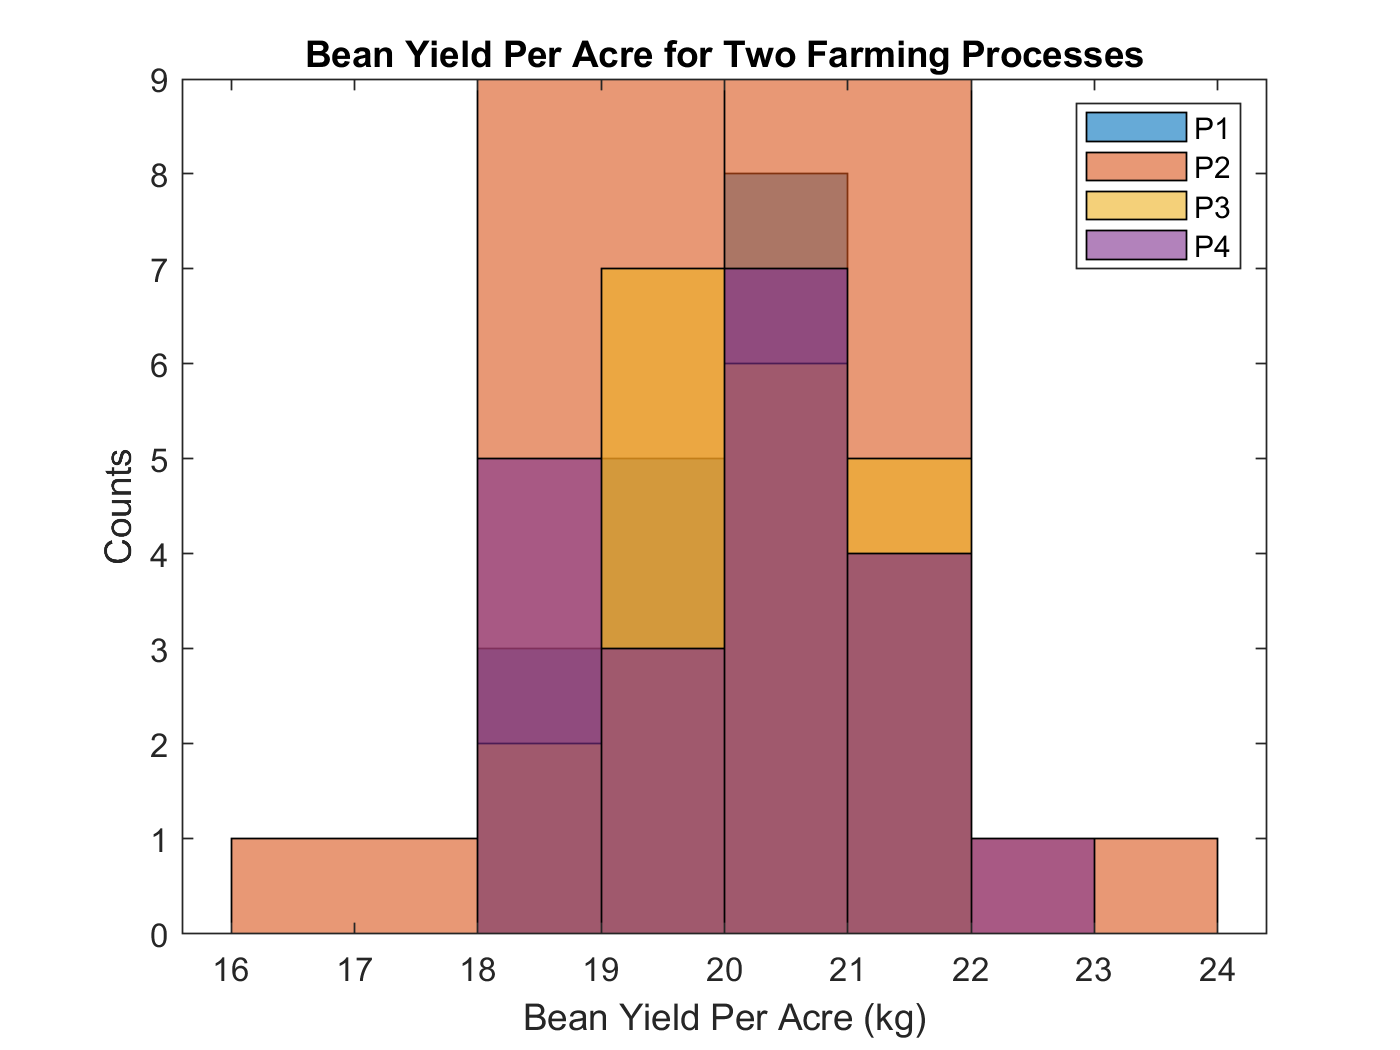

%Obtain the histogram plot of the dataset
figure
histogram(ds(:,1))
hold on
histogram(ds(:,2))
histogram(ds(:,3))
histogram(ds(:,4))
hold off

xlabel('Bean Yield Per Acre (kg)')
ylabel('Counts')
legend('P1','P2','P3','P4', 'Location',"best")
title('Bean Yield Per Acre for Two Farming Processes')


% figure
% histogram(test1,'Normalization','pdf');


### Probability Density Functions

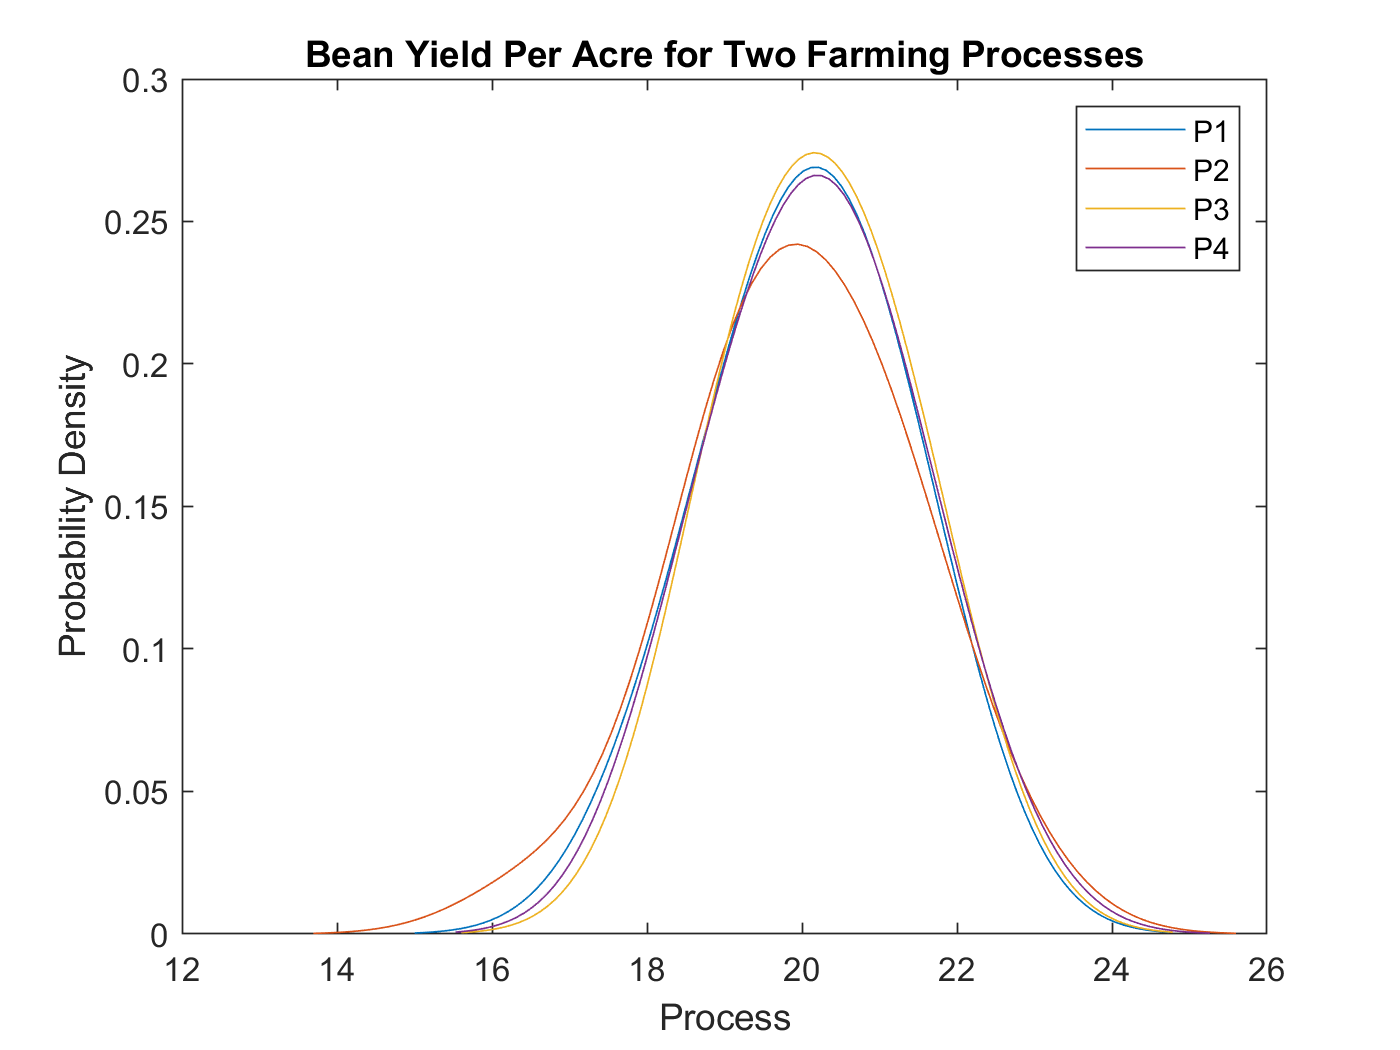

%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
ksdensity(ds(:,1),'Bandwidth',1);
hold on
ksdensity(ds(:,2),'Bandwidth',1);
ksdensity(ds(:,3),'Bandwidth',1);
ksdensity(ds(:,4),'Bandwidth',1);
hold off


xlabel('Process')
ylabel('Probability Density')
legend('P1','P2','P3','P4')
title('Bean Yield Per Acre for Two Farming Processes')

#### Take Aways

From the histograms/pdfs, it looks like means and variances are similar.

### Boxplots

Boxplots are a great way to compare median, IQR (1st to 3rd), and outliers.  In Matlab, the whiskers extend to the farthest data points that are not considered outliers.  The default setting for Matlab is that an outliers is any value more extreme than 1.5*(Q3-Q1) away from the Q1 or Q3 value.

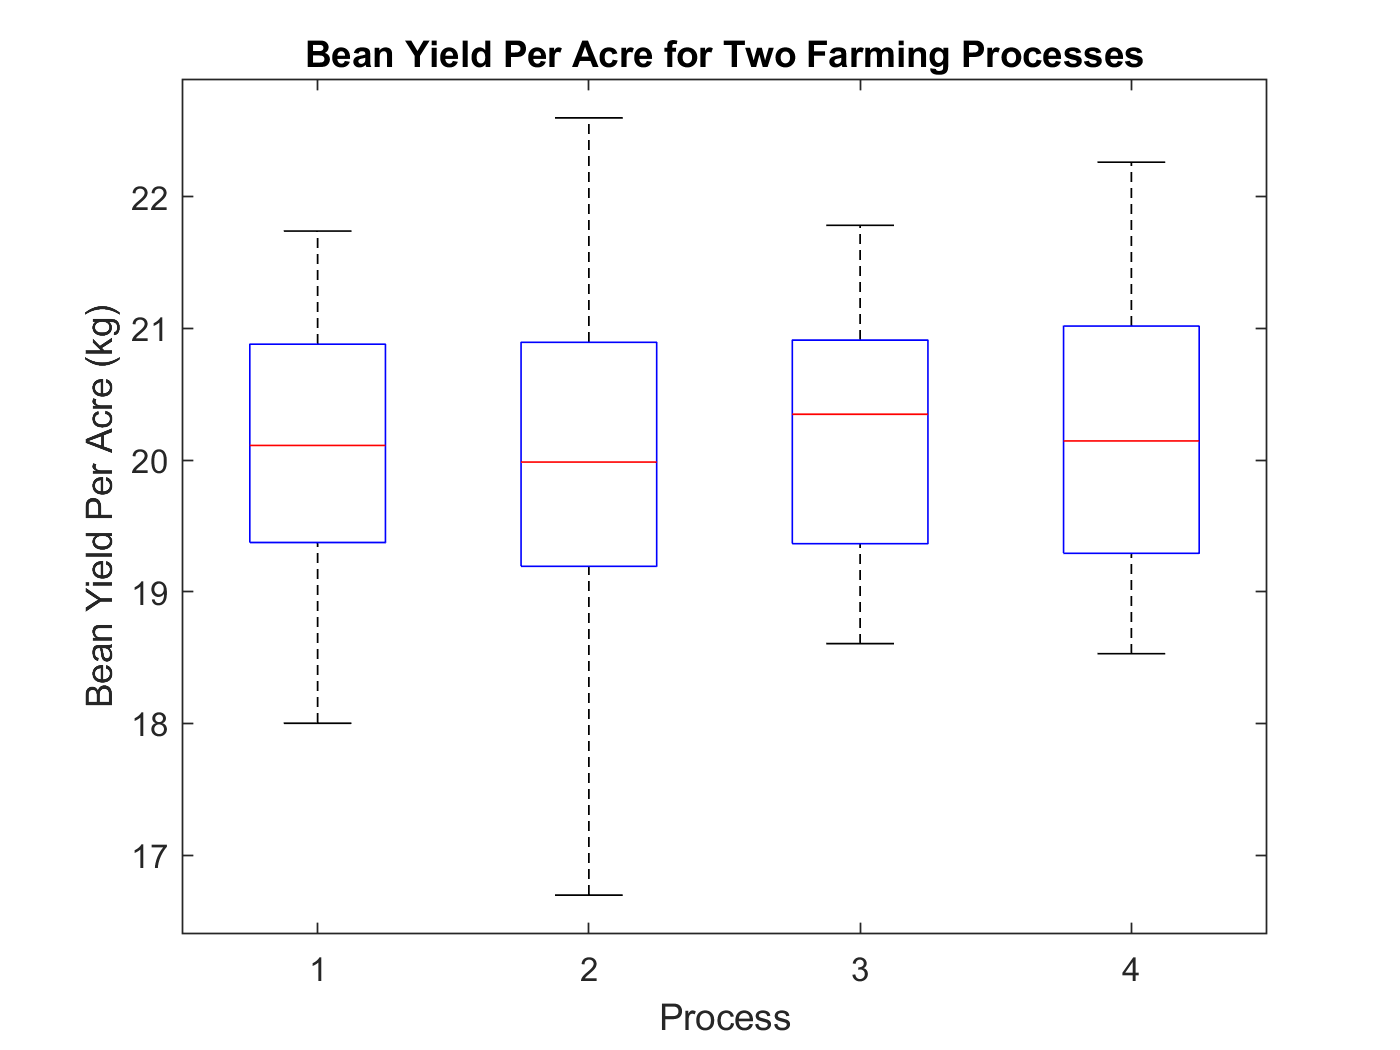

figure
boxplot(ds)
xlabel ('Process')
ylabel ('Bean Yield Per Acre (kg)')
title('Bean Yield Per Acre for Two Farming Processes')

#### Take Aways

These box plots also suggest .

### Scatterplots

If appropriate, plot the data relative to one another.  

This doesn't make sense for this data/problem.

## DESCRIPTIVE STATISTICS - NUMERIC

## Univariate

%Set up a results table
descrStats = table();

descrStats.Mean = mean(ds)';
descrStats.SD = std(ds)';
descrStats.Med = median(ds)';
descrStats.Max = max(ds)';
descrStats.Min = min(ds)';
descrStats.IQR = iqr(ds)';

%Row Labels
descrStats.Properties.RowNames = {'P1','P2','P3','P4'};

descrStats

descrStats = 4×6 table
           Mean       SD        Med       Max       Min       IQR  
          ______    _______    ______    ______    ______    ______

    P1    20.081     1.0719    20.111     21.74    18.001    1.5066
    P2    19.975     1.3536    19.985      22.6    16.695    1.7015
    P3    20.208    0.98249    20.348    21.784    18.606     1.546
    P4    20.178      1.079    20.146    22.263    18.529    1.7262


#### Take Aways

The numeric, univariate statistics also suggest....

### Bivariate

The most common bivariate statistic that we will utilize is the correlation coefficient.

This doesn't make sense to compute for this data/problem.

# INFERENTIAL STATISTICS

Our ultimate goal is to test the difference in means.  However, to do that, we need to first test the normality of the groups.  We also need to know if the groups have equal or unequal variance so that we know what t-test to use in our test of location.

## TEST OF NORMALITY

For a two-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plot

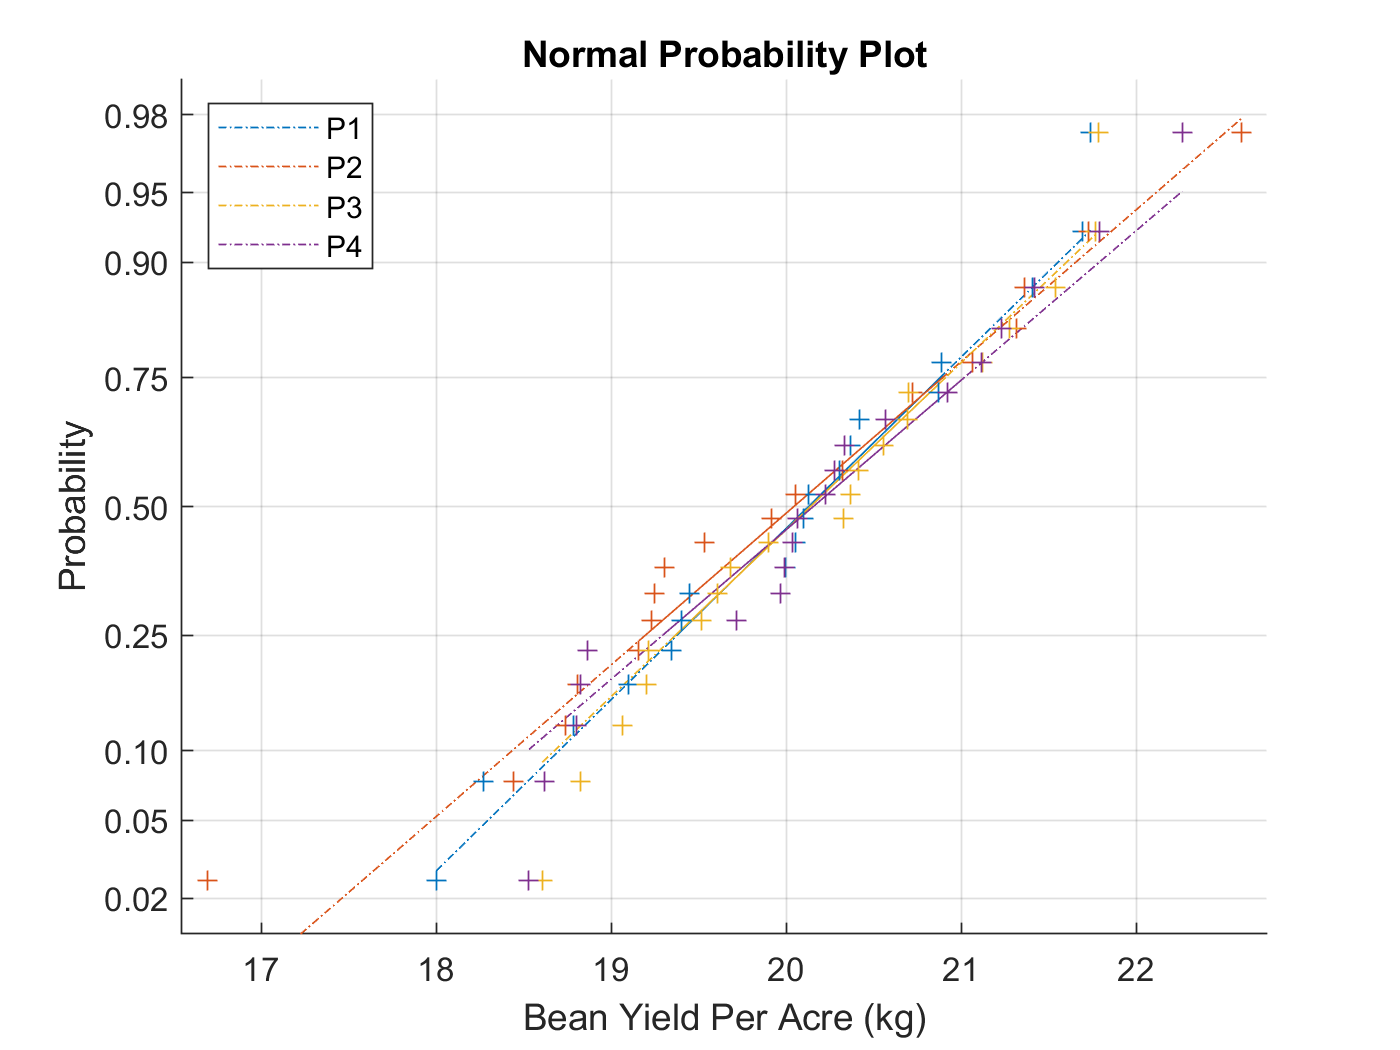

normplot (ds)
legend('P1', 'P2','P3','P4', 'Location', "best")
xlabel('Bean Yield Per Acre (kg)')

The above plot is hard to read, so let's split up the groups.  We will do this along with the AD stat below.

### Anderson-Darling Statistic

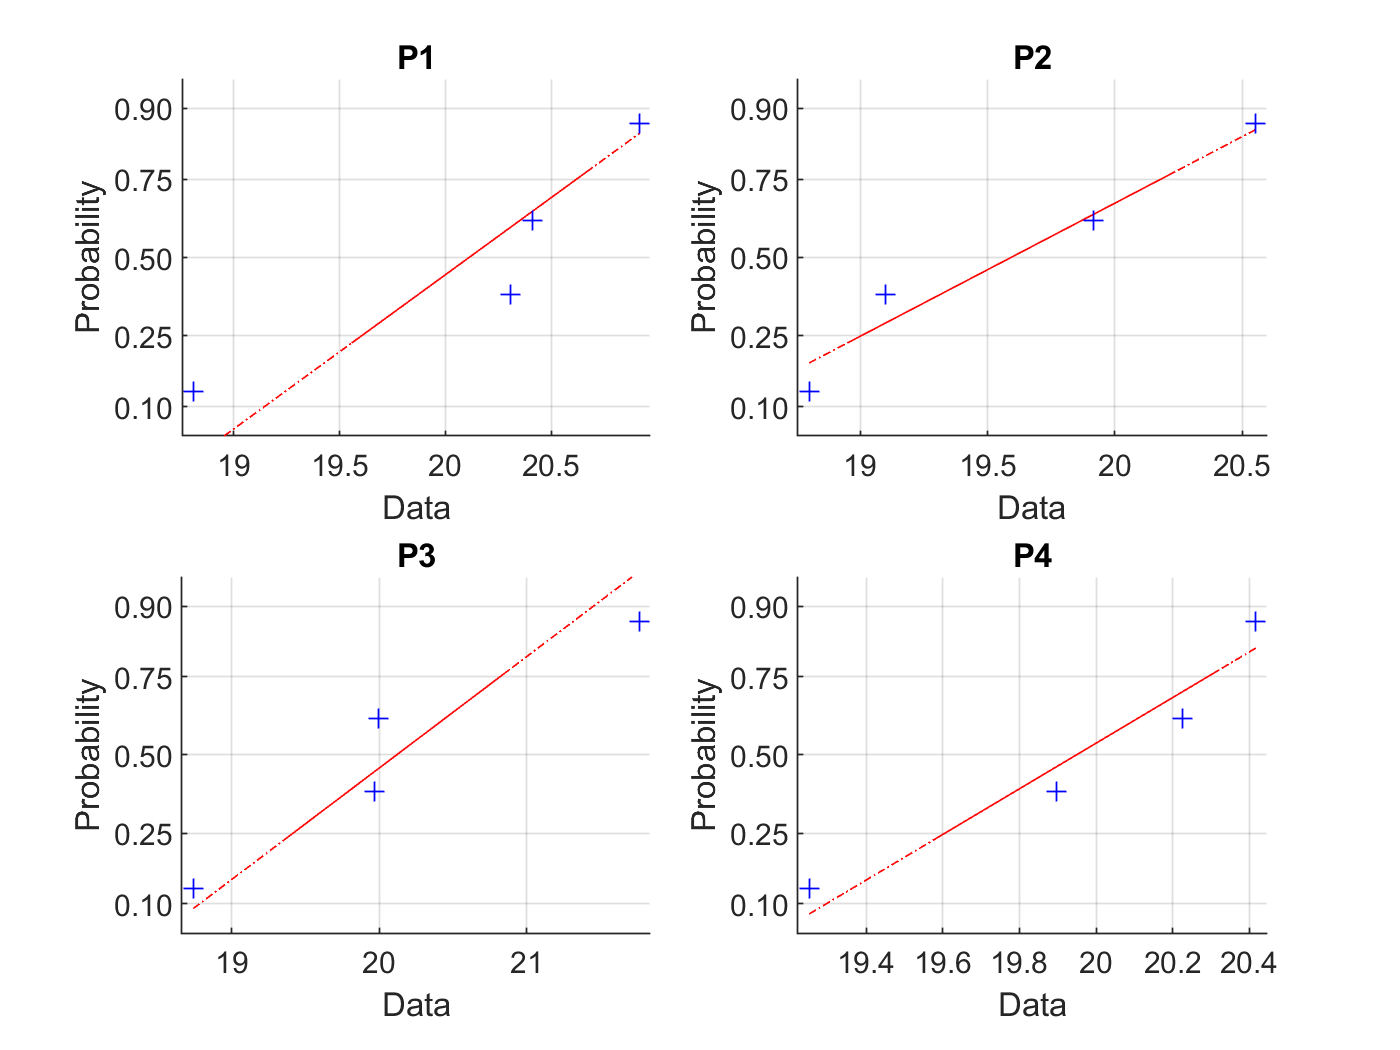

data_labels = {'P1','P2','P3','P4'};

figure
for i=1:size(ds,2)
    subplot(2,2,i)
    normplot(ds(i,:)) %quanlitative check
    title(data_labels(i))

    %anderson-darling test for normality
    % Ho: sample is normal, H1: sample is non-normal
    [h1_norm(i),p1_norm(i), AD_stat(i), cv_norm(i)] = adtest(ds(i,:));
end


h1_norm

h1_norm = 1×4 logical array
   0   0   0   0


p1_norm

p1_norm =     0.2173    0.7412    0.4614    0.6268


Take-away: 

### Decision

Step 7a) Decision : **Fail to Reject H0** (for both groups)

7b) p = see above

7c) WHSSETIT the population from which these data were randomly sampled [**is**]

symmetrical and mesokurtic, and, therefore, [**may**] be approximated by the

Normal distribution. Based on n = _see below____, the ____A-D__ test(s) is appropriate for this

analysis.

n = size(ds,1) 

n = 20

Only one sample size variable is appropriate for this problem because all groups have equal sample size.

## TEST OF VARIANCE

The test of variance will tell us what t-test to use in the test of location.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

- The data are normally distributed (all groups).

Method: For a two-sample, independent test: F test

Step 1 : (Note that a non-directional test is assumed.)

H0 : variance is equal for all groups

H1: variance is not equal across all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use...

Step 4 : We will use ...

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha or F_stat < F_crit

Step 6: Calculations

### Levene test for Variance

[p_var,STATS_var] = vartestn(data','TestType','LeveneAbsolute');

Unrecognized function or variable 'data'.

Notice that the p-value is ... .

### Decision

Step 7a) Decision : ** Fail to Reject H0**

7b) p = _see above__ (greater than alpha)

7c) WHSSETIT the variance(s) of the population from which these samples were drawn are **equal.**

7d) Appropriate Point Estimates

7e) Appropriate Interval Estimates

        I am going to skip this for now.

## TEST OF LOCATION

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a randomly-drawn sample from a process/population (independent specimens).

- **Indep., Equal Var.: Homogeneity of variance (equal variance) may be known or assumed. (???)**

Method: ANOVA (What type??)

Step 1 : (Note that a non-directional test is assumed.)

H0 : All means are equal 

H1: All means are not equal (at least two means are statistically different)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

Step 3 : We will use the ...

Step 4 : We will use the RSD for F with **XX and YY df**

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha or F_stat < F_crit

Step 6: Calculations

[p_ANOVA,ANOVATABLE,STATS_ANOVA] = anova1(ds);


The p-value is XX than alpha. 

### Decision

Step 7a) Decision : **Fail to Reject H0**

7b) p = _see above____ (p greater than alpha)

7c) WHSSETIT the means of the populations from which these samples were drawn are [**equal **]. (If equal: The difference between mu_1 and mu_2 is due to sampling error, and sampling error alone.)

**If reject H0:**

7d) Appropriate Point Estimate(s)

7e) Appropriate Interval Estimate(s)

7f) Effect Size

FOR ANOVA: We will need to find which groups are different, if we reject the null.  We do that through post-hoc analysis.

#### Post-Hoc Analysis

To come...

### Effect Size

## CONCLUSION